

% Montecarlo per modello di Ising in 3 dimensioni


% dichiaro le variabili
Ntot = 128;
N = Ntot/8;
J = 1;
sweeps = 2e4; %ripetizioni
 therm = 1e3;
skip = 500;
beta = [0.1:0.02:0.5]; %linspace(0.1,0.5,20);
Nbeta = length(beta);


M_media = zeros(1,sweeps/skip);
E_media = zeros(1, sweeps/skip);
%averageMtau = zeros(Size, sweeps); %per calcolare l'autocorrelazione nel caso della magnetizzazione
averageM2 =  zeros([1, floor(sweeps/skip)]);
averageM4 =  zeros([1, floor(sweeps/skip)]);
averageE = zeros([1, floor(sweeps/skip)]);
averageE2 =  zeros([1, floor(sweeps/skip)]);


M2 = zeros(size(beta));
M4 = zeros(size(beta));
E = zeros(size(beta));
E2 = zeros(size(beta));
Susc = zeros(size(beta));
C = zeros(size(beta));
U = zeros(size(beta));

errMagn = zeros(size(beta));
errM2 = zeros(size(beta));
errM4 = zeros(size(beta));
errE = zeros(size(beta));
errE2 = zeros(size(beta));
dM = zeros(size(beta));
dM2 = zeros(size(beta));
dM4 = zeros(size(beta));
dE = zeros(size(beta));
dE2 = zeros(size(beta));
dSusc = zeros(size(beta));
dC = zeros(size(beta));
dU = zeros(size(beta));
betac = 0.221652;

Mg = zeros(size(beta));
En = zeros(size(beta));
% definisco l'intervallo di valori di beta per cui studiamo il sistema


% siamo in 3 dimensioni quindi abbiamo 2^3 combinazioni = 8 combinazioni:
%1--p-p-p 2--p-p-d 3--p-d-p 4--d-p-p 5--d-d-p 6--d-p-d 7--p-d-d 8--d-d-d

spin.ppp = sign(0.5 - rand(N,N,N));  %pari-pari-pari
spin.ppd = sign(0.5 - rand(N,N,N));  %pari-pari-dispari
spin.pdp = sign(0.5 - rand(N,N,N));  %pari-dispari-pari
spin.dpp = sign(0.5 - rand(N,N,N));  %dispari-pari-pari
spin.ddp = sign(0.5 - rand(N,N,N));  %dispari-dispari-pari
spin.dpd = sign(0.5 - rand(N,N,N));  %dispari-pari-dispari
spin.pdd = sign(0.5 - rand(N,N,N));  %pari-dispari-dispari
spin.ddd = sign(0.5 - rand(N,N,N));  %dispari-dispari-dispari

hw = waitbar(0, "Musichetta dell'ascensore...");

    %ciclo che si ripete per ogni valore di beta
for cnt = 1:Nbeta
   b = beta(cnt);
   
   for j = 1:therm
       
      spin =  termalizzazione3D(spin, J, b, N);
   end
   
   for s = 1:sweeps
       [spin, E_totale] = evoluz3D(spin, J, b, N);
       
       if rem(s,skip) == 0
       reticolo = cell2mat(struct2cell(spin));
       M_media(s/skip) = sum(sum(sum(reticolo)));       
       E_media(s/skip) = (-1/2).*sum(sum(sum(E_totale)))/(8*N^3);
       averageE2(s/skip) = E_media(s/skip).^2;
                         averageM2(s/skip) = M_media(s/skip).^2;
                          averageM4(s/skip) = averageM2(s/skip).^2;
       
       
       end
   end
   
   
   %En(cnt) = mean(E_media);
 
  %Magnetizzazione media per spin
Mg(cnt) = abs(mean(M_media))/(8*N*N*N);
errMagn(cnt) = std(M_media)/(8*N*N*N);
dM = errMagn./sqrt(sweeps/skip); 
   
   
   % < M^2 > valor medio della magnetizzazione per spin al quadrato
M2(cnt) = mean(averageM2)/(64*N^6);
errM2(cnt) = std(averageM2)/(64*N^6);
dM2 = errM2./sqrt(sweeps/skip);


% < M^4 > valor medio della magnetizzazione per spin alla quarta
M4(cnt) = mean(averageM4)/(4096*N^12);
errM4(cnt) = std(averageM4)/(4096*N^12);
dM4 = errM4./sqrt(sweeps/skip);

%Binder Cumulant U = 1 - < M^4 >/(3*<M^2>^2)

U(cnt) = 1 - M4(cnt)./(3.*M2(cnt).^2);
dU(cnt) = U(cnt).*((6.*M2(cnt).*dM2(cnt) + dM4(cnt))./(3.*M2(cnt).^2 - M4(cnt)) + 2.*dM2(cnt)./M2(cnt));

%Suscettività media Susc = beta.*( < M^2 > - <M>^2 )

Susc(cnt) = b.*(mean(averageM2) - (mean(M_media).^2))./(8*N^3);
dSusc(cnt) = (b./(8*N^3)).*(std(averageM2)./sqrt(sweeps/skip) + 2*mean(M_media).*std(M_media)./sqrt(sweeps/skip));

%Energia media per spin 
E(cnt) = mean(E_media)/(8*N*N*N); 
errE(cnt) = std(E_media)/(8*N*N*N);
dE = errE./sqrt(sweeps/skip);


%< E^2 > valor medio dell'energia per spin al quadrato
E2(cnt) = mean(averageE2)/(4*64*N^6);
errE2(cnt) = std(averageE2)/(4*64*N^6);
dE2 = errE2./sqrt(sweeps/skip);

%calore specifico C = beta^2 .*( < E^2 > - <E>^2 ) dato che Kb = 1

C(cnt) = (b.^2).*( mean(averageE2) - mean(E_media).^2)./(4*8*N^3); 
dC(cnt) = ((b.^2)./(4*8*N^3)).*(std(averageE2)./sqrt(sweeps/skip) + 2*mean(E_media).*std(E_media)./sqrt(sweeps/skip)); 
   
   
    waitbar(cnt/Nbeta);
end
close(hw);


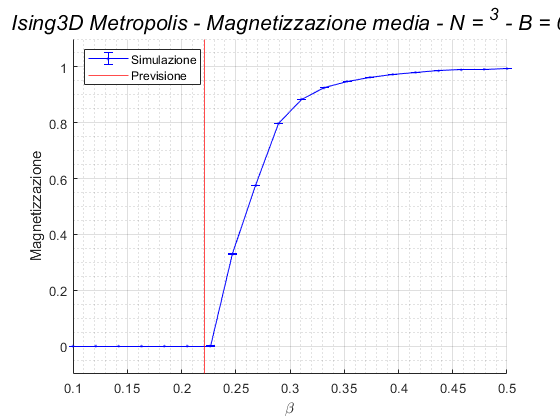


%%%            INIZIO GRAFICO MAGNETIZZAZIONE

fig =figure; % Creiamo la figura
    %set(fig1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising3D Metropolis - Magnetizzazione media - N = ',...
           '^3 - B = 0'],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,Mg,dM,...
             'Color','blue','LineStyle','-','Marker','.',...
             'MarkerSize',4) % Plot della magnetizzazione media (B)
    xline(betac,'r-') % Plot della magnetizzazione secondo la formula esatta
    xlabel('\beta')
    ylabel('Magnetizzazione')          
    legend({'Simulazione','Previsione'},'Location','NorthWest') 
    xlim([0.1 0.5])
    ylim([-0.1 1.1])
 
hold off


%%%            INIZIO GRAFICO ENERGIA MEDIA PER SPIN

fig =figure; % Creiamo la figura
    %set(fig1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising3D Metropolis - Energia media per spin - N = ',...
           '^3 - B = '],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,E*((8*N*N*N)),dE*((8*N*N*N)),...
             'Color','blue','LineStyle','-','Marker','.',...
             'MarkerSize',8) % Plot della energia media (divisa anche per 2)
%     errorbar(beta,Eint,dEint,...
%              'Color','blue','LineStyle','-','Marker','.',...
%              'MarkerSize',8) % Plot della energia media calcolata solo su una coppia
    xline(betac,'r-') % Plot della magnetizzazione secondo la formula esatta
    xlabel('\beta')
    ylabel('Energia media per spin')          
    legend({'Energia divisa per 2','Energia calcolata su una coppia', 'Previsione'},'Location','NorthEast') 

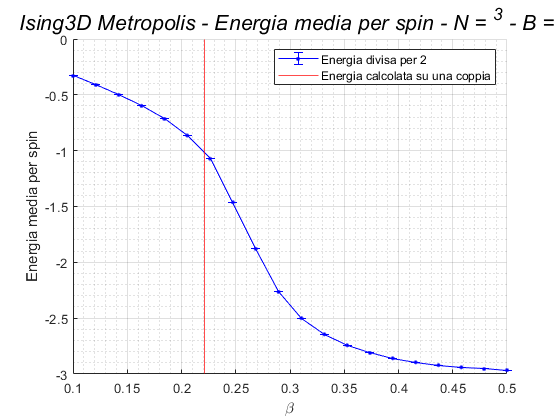



    hold off

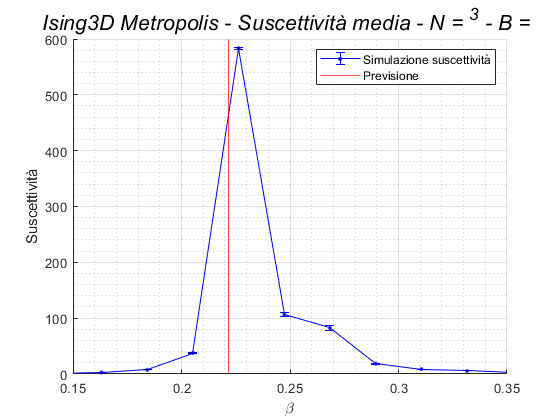

    
    %%%            INIZIO GRAFICO SUSCETTIVITA'

fig =figure; % Creiamo la figura
    %set(fig1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising3D Metropolis - Suscettività media - N = ',...
           '^3 - B = '],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,Susc,dSusc,...
             'Color','blue','LineStyle','-','Marker','.',...
             'MarkerSize',8) % Plot della magnetizzazione media (B)
    xline(betac,'r-') % Plot della magnetizzazione secondo la formula esatta
    xlabel('\beta')
    ylabel('Suscettività')          
    legend({'Simulazione suscettività','Previsione'},'Location','NorthEast') 
    xlim([0.15 0.35])
    
    
    hold off

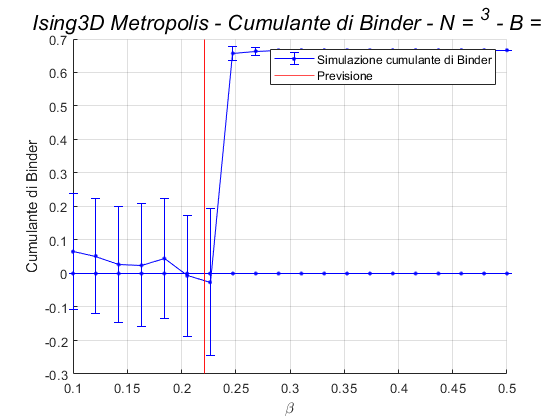

    
    %%%            INIZIO GRAFICO CAPACITA' TERMICA

fig = figure; % Creiamo la figura
    %set(fig1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising3D Metropolis - Capacità termica - N = ',...
           '^3 - B = '],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,C,dC,...
             'Color','blue','LineStyle','-','Marker','.',...
             'MarkerSize',8) % Plot della magnetizzazione media (B)
    xline(betac,'r-') % Plot della magnetizzazione secondo la formula esatta
    xlabel('\beta')
    ylabel('Capacità termica')          
    legend({'Simulazione calore specifico','Previsione'},'Location','NorthEast') 
    
    
    
        %%%            INIZIO GRAFICO CUMULANTE DI BINDER

     
    %set(fig1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising3D Metropolis - Cumulante di Binder - N = ',...
           '^3 - B = '],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,U,dU,...
             'Color','blue','LineStyle','-','Marker','.',...
             'MarkerSize',8) % Plot della magnetizzazione media (B)
    xline(betac,'r-') % Plot della magnetizzazione secondo la formula esatta
    xlabel('\beta')
    ylabel('Cumulante di Binder')          
    legend({'Simulazione cumulante di Binder','Previsione'},'Location','NorthEast') %